clear;
close all;
clc;
load('All_Vari_Sec.mat');       % 包含操作构型和构型变化量的数组
load('All_ConfiVari_Sort.mat');
load('All_RelaConfiVari.mat');
[Min_AllConfiVari,Max_AllConfiVari] = bounds(All_ConfiVari_Sort);
Mea_AllConfiVari = mean(All_ConfiVari_Sort);
[Min_AllRelaConfi, Max_AllRelaConfi] = bounds(All_RelaConfiVari)

Min_AllRelaConfi =      1.846092931908427e-05


Max_AllRelaConfi =    0.993127157512317


Mea_AllRelaConfi = mean(All_RelaConfiVari)

Mea_AllRelaConfi =    0.393373424662849



load('Opti_ConfiVari_Sort.mat');
load('Opti_RelaConfiVari.mat');
load('Opti_RelaMani.mat');

[Min_OptiConfiVari,Max_OptiConfiVari] = bounds(Opti_ConfiVari_Sort);
Mea_OptiConfiVari = mean(Opti_ConfiVari_Sort);
[Min_OptiRelaConfi, Max_OptiRelaConfi] = bounds(Opti_RelaConfiVari)

Min_OptiRelaConfi =    0.237054438002903


Max_OptiRelaConfi =    0.949994108372162


Mea_OptiRelaConfi = mean(Opti_RelaConfiVari)

Mea_OptiRelaConfi =    0.643821183606142


[Min_OptiRelaMani, Max_OptiRelaMani] = bounds(Opti_RelaMani)

Min_OptiRelaMani =    0.403257037419586


Max_OptiRelaMani =    0.875427788734355


Mea_OptiRelaMan = mean(Opti_RelaMani)

Mea_OptiRelaMan =    0.721887120130289


% 计算可操作度
Num_Confi = size(All_Vari_Sec,1);
All_Mani = zeros(Num_Confi,1);
All_RelaMani = zeros(Num_Confi,1);

for jj = 1 : Num_Confi
    Theta_degree = All_Vari_Sec(jj,1:7);
    Theta_rad = Theta_degree * pi / 180;
    Jaco_End = JoiAngToJacMatEnd(Theta_rad);
    Trans_JacoEnd = Jaco_End.';
    Det_JacoEnd = det(Jaco_End * Trans_JacoEnd);
    All_Mani(jj) = sqrt(Det_JacoEnd);
    All_RelaMani(jj) = All_Mani(jj) / 30;   
end
[Min_AllRelaMani, Max_AllRelaMani] = bounds(All_RelaMani)

Min_AllRelaMani =      1.880158336248134e-04


Max_AllRelaMani =    0.880545787402484


Mea_AllRelaMani = mean(All_RelaMani)

Mea_AllRelaMani =    0.279103769849958


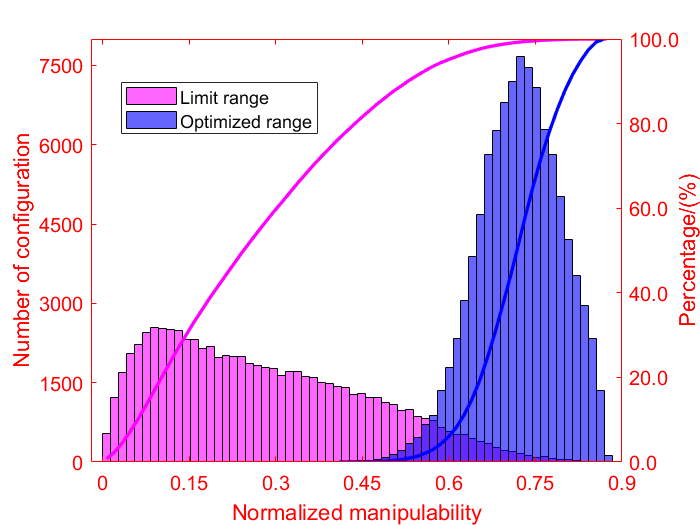

% figure("Position",[100 300 520 440]);
figure;
yyaxis left;
HH_AllRelaMani = histogram(All_RelaMani);
HH_AllRelaMani.BinWidth = 0.0138;
HH_AllRelaMani.FaceColor = [1.00,0.00,1.00];
hold on;
HH_OptiRelaMan = histogram(Opti_RelaMani);
HH_OptiRelaMan.BinWidth = 0.0138;
HH_OptiRelaMan.FaceColor = [0.00,0.00,1.00];
hold off;
yticks(0:1500:7500);
xlim([-0.02 0.90]);
xticks(0:0.15:0.9);
ylabel('Number of configuration',"FontSize",13);      % ,"FontSize",13
set(gca,'YColor',[1.00,0.00,0.00]);
yyaxis right;
[counts_AllRelaMani,centers_AllRelaMani] = hist(All_RelaMani,64);
frequency_AllRelaMani = counts_AllRelaMani / sum(counts_AllRelaMani);
CumFrequency_AllRelaMani = cumsum(frequency_AllRelaMani,2);
figdis_AllRelaMani = plot(centers_AllRelaMani,100 * CumFrequency_AllRelaMani);
figdis_AllRelaMani.Color = [1.00,0.00,1.00];
figdis_AllRelaMani.LineWidth = 2;
hold on;
[counts_OptiRelaMani,centers_OptiRelaMani] = hist(Opti_RelaMani,35);
frequency_OptiRelaMani = counts_OptiRelaMani / sum(counts_OptiRelaMani);
CumFrequency_OptiRelaMani = cumsum(frequency_OptiRelaMani,2);
figdis_OptiRelaMani = plot(centers_OptiRelaMani,100 * CumFrequency_OptiRelaMani,'LineStyle',"-");
figdis_OptiRelaMani.Color = [0.00,0.00,1.00];
figdis_OptiRelaMani.LineWidth = 2;
hold off;
ylim([0 100]);
yticks(0:20:100);
legend('Limit range','Optimized range',"Position",[0.172738071012694,0.744841267752271,0.281071433101381,0.098333335422334]);
xlabel('Normalized manipulability',"FontSize",13);
ylabel ('Percentage/(%)',"VerticalAlignment","middle","FontSize",13);
ytickformat('%.1f');     % 设置百分数小数点后的显示位数
set(gca,'XColor',[1.00,0.00,0.00],'YColor',[1.00,0.00,0.00],'FontSize',12);

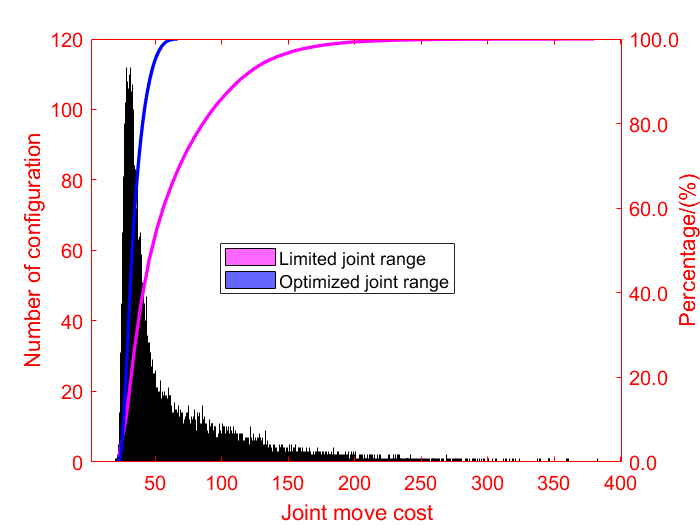

% 统计构型变化量的分布
% figure("Position",[100 300 520 440]);
figure;
yyaxis left;
HH_AllConfiVari = histogram(All_ConfiVari_Sort);
HH_AllConfiVari.BinWidth = 0.0138;
HH_AllConfiVari.FaceColor = [1.00,0.00,1.00];
hold on;
HH_OptiConfiVari = histogram(Opti_ConfiVari_Sort);
HH_OptiConfiVari.BinWidth = 0.0138;
HH_OptiConfiVari.FaceColor = [0.00,0.00,1.00];
hold off;
% yticks(0:1500:7500);
% xlim([-0.02 0.90]);
% xticks(0:0.15:0.9);
ylabel('Number of configuration',"FontSize",13);      % ,"FontSize",13
set(gca,'YColor',[1.00,0.00,0.00]);
yyaxis right;
[counts_AllConfiVari,centers_AllConfiVari] = hist(All_ConfiVari_Sort,64);
frequency_AllConfiVari = counts_AllConfiVari / sum(counts_AllConfiVari);
CumFrequency_AllConfiVari = cumsum(frequency_AllConfiVari,2);
figdis_AllConfiVari = plot(centers_AllConfiVari,100 * CumFrequency_AllConfiVari);
figdis_AllConfiVari.Color = [1.00,0.00,1.00];
figdis_AllConfiVari.LineWidth = 2;
hold on;
[counts_OptiConfiVari,centers_OptiConfiVari] = hist(Opti_ConfiVari_Sort,35);
frequency_OptiConfiVari = counts_OptiConfiVari / sum(counts_OptiConfiVari);
CumFrequency_OptiConfiVari = cumsum(frequency_OptiConfiVari,2);
figdis_OptiConfiVari = plot(centers_OptiConfiVari,100 * CumFrequency_OptiConfiVari,'LineStyle',"-");
figdis_OptiConfiVari.Color = [0.00,0.00,1.00];
figdis_OptiConfiVari.LineWidth = 2;
hold off;
ylim([0 100]);
yticks(0:20:100);
legend('Limited joint range','Optimized joint range','Position',[0.314880953941039,0.439186507096368,0.335357148681368,0.098333335422334]);
xlabel('Joint move cost',"FontSize",13);
ylabel ('Percentage/(%)',"VerticalAlignment","middle","FontSize",13);
ytickformat('%.1f');     % 设置百分数小数点后的显示位数
set(gca,'XColor',[1.00,0.00,0.00],'YColor',[1.00,0.00,0.00],'FontSize',12);

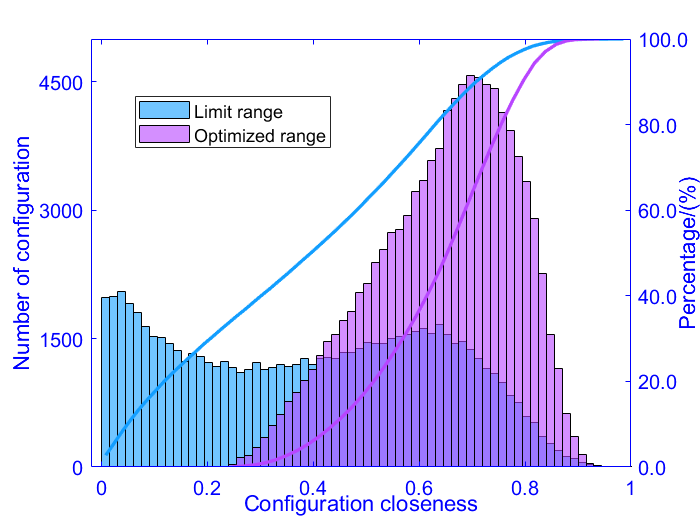

% 统计相对构型近似度的分布规律
% figure("Position",[100 300 520 440]);
figure;
yyaxis left;
HH_AllRelaConfiVari = histogram(All_RelaConfiVari);        % All_RelaConfiVari
HH_AllRelaConfiVari.BinWidth = 0.015;
HH_AllRelaConfiVari.FaceColor = [0.07,0.62,1.00];
hold on;
HH_OptiRelaConfiVari = histogram(Opti_RelaConfiVari);
HH_OptiRelaConfiVari.BinWidth = 0.015;
HH_OptiRelaConfiVari.FaceColor = [0.72,0.27,1.00];
hold off;

yticks(0:1500:6000);
xlim([-0.02 1.0]);
xticks(0:0.2:1.0);
ylabel('Number of configuration',"FontSize",13);      % ,"FontSize",13
set(gca,'YColor',[0.00,0.00,1.00]);
yyaxis right;
[counts_AllRelaConfiVari,centers_AllRelaConfiVari] = hist(All_RelaConfiVari,64);
frequency_AllRelaConfiVari = counts_AllRelaConfiVari / sum(counts_AllRelaConfiVari);
CumFrequency_AllRelaConfiVari = cumsum(frequency_AllRelaConfiVari,2);
figdis_AllRelaConfiVari = plot(centers_AllRelaConfiVari,100 * CumFrequency_AllRelaConfiVari);
figdis_AllRelaConfiVari.Color = [0.07,0.62,1.00];
figdis_AllRelaConfiVari.LineWidth = 2;
hold on;
[counts_OptiRelaConfiVari,centers_OptiRelaConfiVari] = hist(Opti_RelaConfiVari,35);
frequency_OptiRelaConfiVari = counts_OptiRelaConfiVari / sum(counts_OptiRelaConfiVari);
CumFrequency_OptiRelaConfiVari = cumsum(frequency_OptiRelaConfiVari,2);
figdis_OptiRelaConfiVari = plot(centers_OptiRelaConfiVari,100 * CumFrequency_OptiRelaConfiVari,'LineStyle',"-");
figdis_OptiRelaConfiVari.Color = [0.72,0.27,1.00];
figdis_OptiRelaConfiVari.LineWidth = 2;
hold off;
ylim([0 100]);
yticks(0:20:100);
legend('Limit range','Optimized range','Position',[0.192380949639139,0.718392856098362,0.281071433101381,0.098333335422334]);
xlabel('Configuration closeness','VerticalAlignment',"middle","FontSize",13);
ylabel ('Percentage/(%)',"VerticalAlignment","baseline","FontSize",13);
ytickformat('%.1f');     % 设置百分数小数点后的显示位数
set(gca,'XColor',[0.00,0.00,1.00],'YColor',[0.00,0.00,1.00],'FontSize',12);

% 计算极限范围和优化范围内的目标函数值
All_TarFunc = zeros(Num_Confi,1);
for ii = 1 : Num_Confi
    All_TarFunc(ii) = 0.7 * All_RelaMani(ii) + 0.3 * All_RelaConfiVari(ii);
end
Num_OptiConfi = size(Opti_RelaConfiVari,1);
Opti_TarFunc = zeros(Num_OptiConfi,1);
for ii = 1 : Num_OptiConfi
    Opti_TarFunc(ii) = 0.7 * Opti_RelaMani(ii) + 0.3 * Opti_RelaConfiVari(ii);
end
[Min_AllTarFunc, Max_AllTarFunc] = bounds(All_TarFunc)

Min_AllTarFunc =      1.517295850801802e-04


Max_AllTarFunc =    0.839286773706663


Mea_AllTarFunc = mean(All_TarFunc)

Mea_AllTarFunc =    0.313384666293826


[Min_OptiTarFunc, Max_OptiTarFunc] = bounds(Opti_TarFunc)

Min_OptiTarFunc =    0.395125119513209


Max_OptiTarFunc =    0.882667222396508


Mea_OptiTarFunc = mean(Opti_TarFunc)

Mea_OptiTarFunc =    0.698467339173045


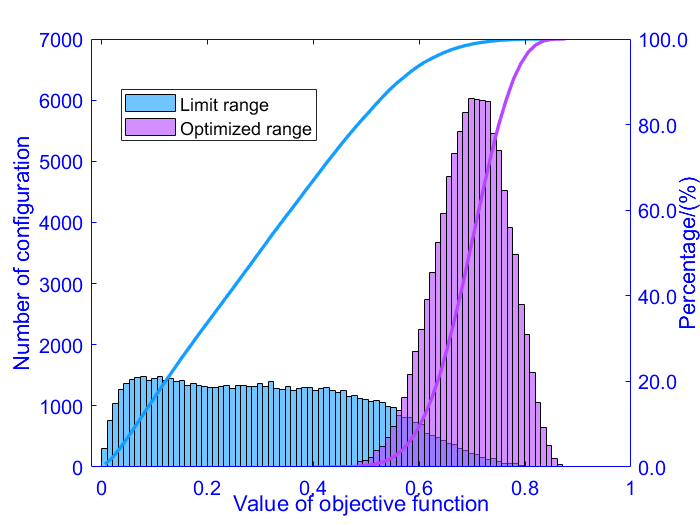

figure;
yyaxis left;
HH_AllTarFunc = histogram(All_TarFunc);        % All_RelaConfiVari
HH_AllTarFunc.BinWidth = 0.0105;
HH_AllTarFunc.FaceColor = [0.07,0.62,1.00];
hold on;
HH_OptiTarFunc = histogram(Opti_TarFunc);
HH_OptiTarFunc.BinWidth = 0.0105;
HH_OptiTarFunc.FaceColor = [0.72,0.27,1.00];
hold off;

% yticks(0:2000:8000);
xlim([-0.02 1.0]);
xticks(0:0.2:1.0);
ylabel('Number of configuration',"FontSize",13);      % ,"FontSize",13
set(gca,'YColor',[0.00,0.00,1.00]);
yyaxis right;
[counts_AllTarFunc,centers_AllTarFunc] = hist(All_TarFunc,64);
frequency_AllTarFunc = counts_AllTarFunc / sum(counts_AllTarFunc);
CumFrequency_AllTarFunc = cumsum(frequency_AllTarFunc,2);
figdis_AllTarFunc = plot(centers_AllTarFunc,100 * CumFrequency_AllTarFunc);
figdis_AllTarFunc.Color = [0.07,0.62,1.00];
figdis_AllTarFunc.LineWidth = 2;
hold on;
[counts_OptiTarFunc,centers_OptiTarFunc] = hist(Opti_TarFunc,35);
frequency_OptiTarFunc = counts_OptiTarFunc / sum(counts_OptiTarFunc);
CumFrequency_OptiTarFunc = cumsum(frequency_OptiTarFunc,2);
figdis_OptiTarFunc = plot(centers_OptiTarFunc,100 * CumFrequency_OptiTarFunc,'LineStyle',"-");
figdis_OptiTarFunc.Color = [0.72,0.27,1.00];
figdis_OptiTarFunc.LineWidth = 2;
hold off;
ylim([0 100]);
yticks(0:20:100);
legend('Limit range','Optimized range','Position',[0.172380949639139,0.731726189431697,0.281071433101381,0.098333335422334]);
xlabel('Value of objective function','VerticalAlignment',"middle","FontSize",13);
ylabel ('Percentage/(%)',"VerticalAlignment","baseline","FontSize",13);
ytickformat('%.1f');     % 设置百分数小数点后的显示位数
set(gca,'XColor',[0.00,0.00,1.00],'YColor',[0.00,0.00,1.00],'FontSize',12);


% 分析各关节对目标函数值的影响
All_ConfiAndTarFunc = [All_Vari_Sec, All_TarFunc];
Vari_Desc = sortrows(All_ConfiAndTarFunc,9,'descend');         % 按照降序重新排列
Confi_Thou = Vari_Desc(1:1000,1:7);
Vari_Joi1 = Confi_Thou(:,1);
Vari_Joi2 = Confi_Thou(:,2);
Vari_Joi3 = Confi_Thou(:,3);
Vari_Joi4 = Confi_Thou(:,4);
Vari_Joi5 = Confi_Thou(:,5);
Vari_Joi6 = Confi_Thou(:,6);
Vari_Joi7 = Confi_Thou(:,7);

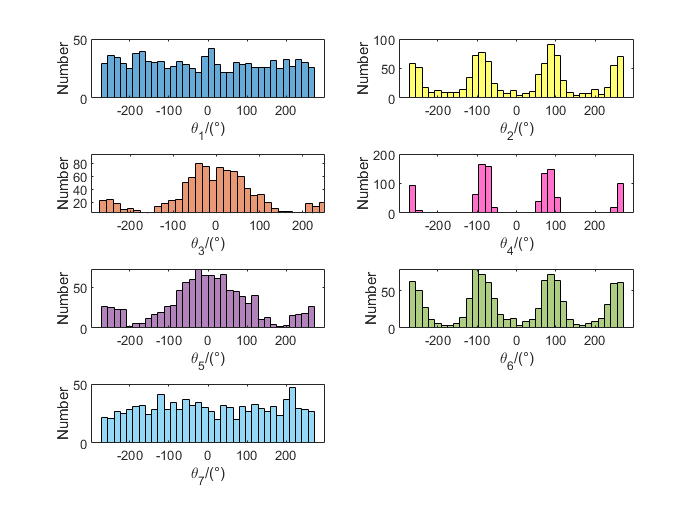

% 绘制关节角度分布规律
figure;
subplot(4,2,1);
Fig_Joi1 = histogram(Vari_Joi1);
Fig_Joi1.BinWidth = 16;
xlabel ('\theta_1/(°)');
ylabel ('Number');
subplot(4,2,2);
Fig_Joi2 = histogram(Vari_Joi2);
Fig_Joi2.BinWidth = 16;
Fig_Joi2.FaceColor = [1.00 1.00 0.07];
xlabel ('\theta_2/(°)');
ylabel ('Number');
subplot(4,2,3);
Fig_Joi3 = histogram(Vari_Joi3);
Fig_Joi3.BinWidth = 16;
Fig_Joi3.FaceColor = [0.8500 0.3250 0.0980];
xlabel ('\theta_3/(°)');
ylabel ('Number');
subplot(4,2,4);
Fig_Joi4 = histogram(Vari_Joi4);
Fig_Joi4.BinWidth = 16;
xlabel ('\theta_4/(°)');
ylabel ('Number');
Fig_Joi4.FaceColor = [1.00,0.07,0.65];
subplot(4,2,5);
Fig_Joi5 = histogram(Vari_Joi5);
Fig_Joi5.BinWidth = 16;
xlabel ('\theta_5/(°)');
ylabel ('Number');
Fig_Joi5.FaceColor = [0.4940 0.1840 0.5560];
subplot(4,2,6);
Fig_Joi6 = histogram(Vari_Joi6);
Fig_Joi6.BinWidth = 16;
xlabel ('\theta_6/(°)');
ylabel ('Number');
Fig_Joi6.FaceColor = [0.4660 0.6740 0.1880];
subplot(4,2,7);
Fig_Joi7 = histogram(Vari_Joi7);
Fig_Joi7.BinWidth = 16;
xlabel ('\theta_7/(°)');
ylabel ('Number');
Fig_Joi7.FaceColor = [0.3010 0.7450 0.9330];

save('Vari_Joi1.mat','Vari_Joi1');
save('Vari_Joi2.mat','Vari_Joi2');
save('Vari_Joi3.mat','Vari_Joi3');
save('Vari_Joi4.mat','Vari_Joi4');
save('Vari_Joi5.mat','Vari_Joi5');
save('Vari_Joi6.mat','Vari_Joi6');
save('Vari_Joi7.mat','Vari_Joi7');

% 程序所用函数

function Jaco_end = JoiAngToJacMatEnd(Theta)
%%   根据输入的关节角度计算雅克比矩阵
%   输入量为包含7个关节角度的数组，单位为rad；
%   输出量为使用旋量法以末端坐标系为参考的雅可比矩阵；
%   使用旋量法求解得到的雅可比矩阵前三列是角速度，后三列是线速度，与DH法的相反；
%% 单位转化
% Theta_rad = Theta * pi /180;
Theta_rad = Theta;
%% 机械臂关节常量定义
a0N = 0.7161;
a1N = 0.430;
a2N = 0.430;
a3N = 2.080;
a4N = 0.387;
a5N = 2.080;
a6N = 0.430;
a7N = 0.430;
a8N = 0.7161;
%% 关节角度赋值
theta1 = Theta_rad(1);
theta2 = Theta_rad(2);
theta3 = Theta_rad(3);
theta4 = Theta_rad(4);
theta5 = Theta_rad(5);
theta6 = Theta_rad(6);
theta7 = Theta_rad(7);
%% 求解公式
Je_B1 = [cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6);
        sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)))) - cos(theta2)*cos(theta7)*sin(theta6);
        sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) + cos(theta2)*sin(theta6)*sin(theta7);
        a3N*cos(theta2)*sin(theta4)*sin(theta5)*sin(theta6) - a7N*cos(theta2)*sin(theta6) - a3N*cos(theta3)*cos(theta6)*sin(theta2) - a5N*cos(theta2)*cos(theta5)*sin(theta6) - a3N*cos(theta2)*cos(theta4)*cos(theta5)*sin(theta6) - a5N*cos(theta3)*cos(theta4)*cos(theta6)*sin(theta2) - a1N*cos(theta6)*sin(theta2) + a5N*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta4) - a1N*cos(theta2)*cos(theta3)*cos(theta4)*cos(theta5)*sin(theta6) - a7N*cos(theta3)*cos(theta4)*cos(theta5)*cos(theta6)*sin(theta2) + a1N*cos(theta2)*cos(theta3)*sin(theta4)*sin(theta5)*sin(theta6) + a1N*cos(theta2)*cos(theta4)*sin(theta3)*sin(theta5)*sin(theta6) + a1N*cos(theta2)*cos(theta5)*sin(theta3)*sin(theta4)*sin(theta6) + a2N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a2N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a2N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a4N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a4N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a4N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a6N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a6N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a6N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a7N*cos(theta3)*cos(theta6)*sin(theta2)*sin(theta4)*sin(theta5) + a7N*cos(theta4)*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta5) + a7N*cos(theta5)*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta4) - a2N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6) - a4N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6) - a6N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6);
        (cos(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4))) + cos(theta7)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) + (cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6))*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) + sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))))*(a2N + a4N + a6N + a8N) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))*(a3N + a5N + a7N) + sin(theta6)*sin(theta7)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) - (sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) + cos(theta2)*sin(theta6)*sin(theta7))*(a8N*(cos(theta6) - 1) + cos(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6)*(a2N + a4N + a6N + a8N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N));
        (cos(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) - sin(theta2)*sin(theta6)*sin(theta7))*(a1N + a3N + a5N + a7N) - (cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6))*((cos(theta3) - 1)*(a3N + a5N + a7N)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)) + (a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) + sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)))*(a2N + a4N + a6N + a8N) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) - cos(theta7)*sin(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) + (sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4))) - cos(theta2)*cos(theta7)*sin(theta6))*(a8N*(cos(theta6) - 1) + cos(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6)*(a2N + a4N + a6N + a8N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N))];
Je_B2 = [sin(theta3 + theta4 + theta5)*sin(theta6);
        cos(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7))) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)));
        cos(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)));
        (a5N*sin(theta3 + theta4 - theta6))/2 + (a2N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a4N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a6N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a7N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a3N*sin(theta3 + theta6))/2 - (a2N*sin(theta3 + theta4 + theta5 - theta6))/2 - (a4N*sin(theta3 + theta4 + theta5 - theta6))/2 - (a6N*sin(theta3 + theta4 + theta5 - theta6))/2 + (a7N*sin(theta3 + theta4 + theta5 - theta6))/2 + (a3N*sin(theta3 - theta6))/2 + (a5N*sin(theta3 + theta4 + theta6))/2;
        sin(theta3 + theta4 + theta5)*sin(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))*(a3N + a5N + a7N) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) - (cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)))*(a2N + a4N + a6N + a8N) - (cos(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))))*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N));
        (cos(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7))) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))))*(a8N*(cos(theta6) - 1) - sin(theta3)*(sin(theta4)*sin(theta5)*sin(theta6) - cos(theta4)*cos(theta5)*sin(theta6))*(a3N + a5N + a7N) + (cos(theta3) - 1)*(cos(theta4)*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6))*(a3N + a5N + a7N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1)) - (cos(theta3)*(cos(theta4)*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)) - sin(theta3)*(sin(theta4)*sin(theta5)*sin(theta6) - cos(theta4)*cos(theta5)*sin(theta6)))*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)))*(a3N + a5N + a7N) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) - (cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))))*(a2N + a4N + a6N + a8N)];
Je_B3 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -sin(theta6)*(a7N + a3N*cos(theta4 + theta5) + a5N*cos(theta5));
        cos(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) + (cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) - sin(theta6)*sin(theta7)*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1));
        (cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) - cos(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) - cos(theta7)*sin(theta6)*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1))];
Je_B4 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -sin(theta6)*(a7N + a5N*cos(theta5));
        a5N*sin(theta5)*sin(theta7) - a7N*cos(theta6)*cos(theta7) + a8N*sin(theta6)*sin(theta7) - a5N*cos(theta5)*cos(theta6)*cos(theta7);
        a5N*cos(theta7)*sin(theta5) + a7N*cos(theta6)*sin(theta7) + a8N*cos(theta7)*sin(theta6) + a5N*cos(theta5)*cos(theta6)*sin(theta7)];
Je_B5 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -a7N*sin(theta6);
        a8N*sin(theta6)*sin(theta7) - a7N*cos(theta6)*cos(theta7);
        a7N*cos(theta6)*sin(theta7) + a8N*cos(theta7)*sin(theta6)];
Je_B6 = [0;
        sin(theta7);
        cos(theta7);
        0;
        a8N*cos(theta7);
        -a8N*sin(theta7)];
Je_B7 = [1;
        0;
        0;
        0;
        0;
        0];

Jaco_lad = [Je_B1   Je_B2   Je_B3   Je_B4   Je_B5   Je_B6   Je_B7];     % 前三列是角速度，后三列是线速度J = [w;v]
Jaco_end = [Jaco_lad(4:6,:);Jaco_lad(1:3,:)];
end
